# FF_OPTIM_MLSEC_SAVEZRONE Derivative Multisection

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**ff_optim_mlsec_savezrone**](https://github.com/FanWangEcon//MEconTools/blob/master/MEconTools/optim/ff_optim_mlsec_savezrone.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **This functions solves for optimal savings/borrowing level given an anonymous function that provides the derivative of a intertemporal savings problem. This is a vectorized function solved with multi-section (multiple points bisection concurrently).

The vectorized and looped bisection savings problem rely on this function to solve for optimal savings choices:

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand ***Loop***:[** ff_vfi_az_bisec_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_loop.m), high precision even with small grid

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand ***Vectorized***: [**ff_vfi_az_bisec_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_vec.m), precision and speed

## Test FF_OPTIM_MLSEC_SAVEZRONE One Individual

Bisection for savings choice at one state:

% Generate the state-space and function
[fl_z1, fl_z2, fl_r, fl_beta] = deal(0.4730, 0.6252, 0.0839, 0.7365);
% ffi_intertemporal_max is a function in ff_optim_mlsec_savezrone for testing
fc_deri_wth_uniroot = @(x) ffi_intertemporal_max(x, fl_z1, fl_z2, fl_r, fl_beta);
% Call Function
bl_verbose = false;
bl_timer = true;
% optimally borrowing given the parameters here
mp_mlsec_ctrlinfo = containers.Map('KeyType','char', 'ValueType','any');
mp_mlsec_ctrlinfo('it_mzoom_jnt_pnts') = 10;
mp_mlsec_ctrlinfo('it_mzoom_max_iter') = 4;
[fl_opti_save_frac, fl_opti_save_level] = ...
    ff_optim_mlsec_savezrone(fc_deri_wth_uniroot, bl_verbose, bl_timer, mp_mlsec_ctrlinfo)

Elapsed time is 0.002805 seconds.


fl_opti_save_frac = 0.4241

fl_opti_save_level = -0.1316

## Test FF_OPTIM_MLSEC_SAVEZRONE 5 Individuals 5 Iterations 5 Points Per Iteration

5 grid points per iteration, and 5 iterations.

    iter    cl_row_names_a     Var1       Var2       Var3       Var4       Var5       Var6  
    ____    ______________    _______    _______    _______    _______    _______    _______

     0        "point=1"         1e-05      1e-05      1e-05      1e-05      1e-05      1e-05
     1        "point=1"         1e-05      1e-05      1e-05      1e-05      1e-05      1e-05
     1        "point=2"       0.25001    0.25001    0.25001    0.25001    0.25001    0.25001
     1        "point=3"           0.5        0.5        0.5        0.5        0.5        0.5
     1        "point=4"          0.75       0.75       0.75       0.75       0.75       0.75
     1        "point=5"       0.99999    0.99999    0.99999    0.99999    0.

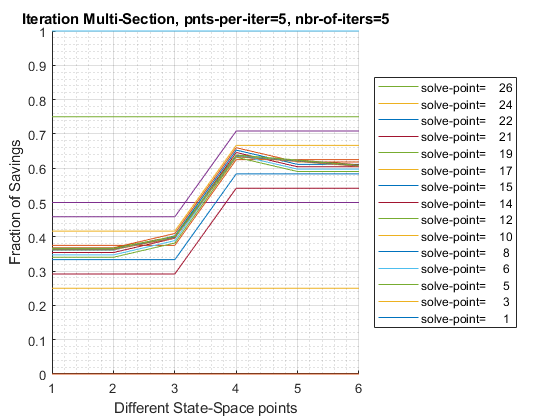

Elapsed time is 0.406584 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_container_map ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                         i    idx    ndim    numel    rowN    colN        sum           mean           std        coefvari        min           max    
                         _    ___    ____    _____    ____    ____    ___________    ___________    __________    ________    ___________    __________

    ar_opti_foc_obj      1     1      2        6       6  

% Generate the state-space and function
rng(123);
it_draws = 6; % must be even number
ar_z1 = exp(rand([it_draws,1])*3-1.5);
ar_z2 = exp(rand([it_draws,1])*3-1.5);
ar_r = (rand(it_draws,1)*10.0);
ar_beta = [rand(round(it_draws/2),1)*0.9+0.1; rand(round(it_draws/2),1)*0.9+1]; 
fc_deri_wth_uniroot = @(x) ffi_intertemporal_max(x, ar_z1, ar_z2, ar_r, ar_beta);
% Call Function
bl_verbose = true;
bl_timer = true;
mp_mlsec_ctrlinfo = containers.Map('KeyType','char', 'ValueType','any');
mp_mlsec_ctrlinfo('it_mlsect_jnt_pnts') = 5;
mp_mlsec_ctrlinfo('it_mlsect_max_iter') = 5;
ff_optim_mlsec_savezrone(fc_deri_wth_uniroot, bl_verbose, bl_timer, mp_mlsec_ctrlinfo);

## Test FF_OPTIM_MLSEC_SAVEZRONE 8 Individuals 3 Iterations 10 Points Per Iteration

10 grid points per iteration, and 3 iterations.

    iter    cl_row_names_a     Var1       Var2       Var3       Var4       Var5       Var6       Var7       Var8  
    ____    ______________    _______    _______    _______    _______    _______    _______    _______    _______

     0        "point=1"         1e-05      1e-05      1e-05      1e-05      1e-05      1e-05      1e-05      1e-05
     1        "point=1"         1e-05      1e-05      1e-05      1e-05      1e-05      1e-05      1e-05      1e-05
     1        "point=2"       0.11112    0.11112    0.11112    0.11112    0.11112    0.11112    0.11112    0.11112
     1        "point=3"       0.22223    0.22223    0.22223    0.22223    0.22223   

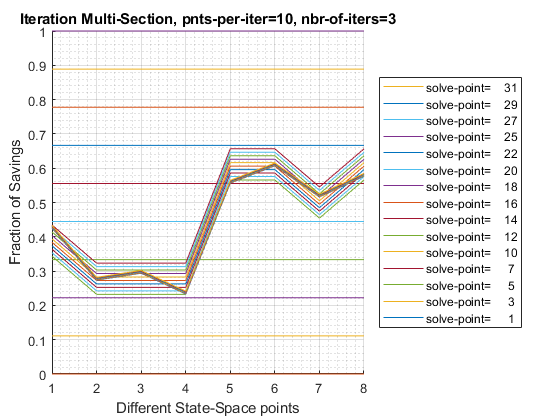

Elapsed time is 0.633499 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_container_map ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                         i    idx    ndim    numel    rowN    colN       sum          mean          std       coefvari       min           max   
                         _    ___    ____    _____    ____    ____    _________    __________    _________    ________    __________    _________

    ar_opti_foc_obj      1     1      2        8       8       1      

% Generate the state-space and function
rng(123);
it_draws = 8; % must be even number
ar_z1 = exp(rand([it_draws,1])*3-1.5);
ar_z2 = exp(rand([it_draws,1])*3-1.5);
ar_r = (rand(it_draws,1)*10.0);
ar_beta = [rand(round(it_draws/2),1)*0.9+0.1; rand(round(it_draws/2),1)*0.9+1]; 
fc_deri_wth_uniroot = @(x) ffi_intertemporal_max(x, ar_z1, ar_z2, ar_r, ar_beta);
% Call Function
bl_verbose = true;
bl_timer = true;
mp_mlsec_ctrlinfo = containers.Map('KeyType','char', 'ValueType','any');
mp_mlsec_ctrlinfo('it_mlsect_jnt_pnts') = 10;
mp_mlsec_ctrlinfo('it_mlsect_max_iter') = 3;
ff_optim_mlsec_savezrone(fc_deri_wth_uniroot, bl_verbose, bl_timer, mp_mlsec_ctrlinfo);

## Test FF_OPTIM_MLSEC_SAVEZRONE Speed

Test Speed doing 6.25 million multisections for a savings problem:

% Generate the state-space and function
rng(123);
it_draws = 6250000; % must be even number
ar_z1 = exp(rand([it_draws,1])*3-1.5);
ar_z2 = exp(rand([it_draws,1])*3-1.5);
ar_r = (rand(it_draws,1)*10.0);
ar_beta = [rand(round(it_draws/2),1)*0.9+0.1; rand(round(it_draws/2),1)*0.9+1]; 
% ffi_intertemporal_max is a function in ff_optim_mlsec_savezrone for testing
fc_deri_wth_uniroot = @(x) ffi_intertemporal_max(x, ar_z1, ar_z2, ar_r, ar_beta);
% Call Function
bl_verbose = false;
bl_timer = true;
[ar_opti_save_frac, ar_opti_save_level] = ff_optim_mlsec_savezrone(fc_deri_wth_uniroot, bl_verbose, bl_timer);

Elapsed time is 13.672896 seconds.


mp_container_map = containers.Map('KeyType','char', 'ValueType','any');
mp_container_map('ar_opti_save_frac') = ar_opti_save_frac;
mp_container_map('ar_opti_save_level') = ar_opti_save_level;
mp_container_map('ar_opti_save_frac_notnan') = ar_opti_save_frac(~isnan(ar_opti_save_frac));
ff_container_map_display(mp_container_map);

----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_container_map ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                                i    idx    ndim     numel        rowN      colN       sum         mean        std      coefvari      min         max  
                                _    ___    ____    ________    ________    ____    __________    _______    _______    ________    ________    _______

    ar_opti_save_frac           1     1      2      6.25e+06    6.25e+06     1       2.884e+

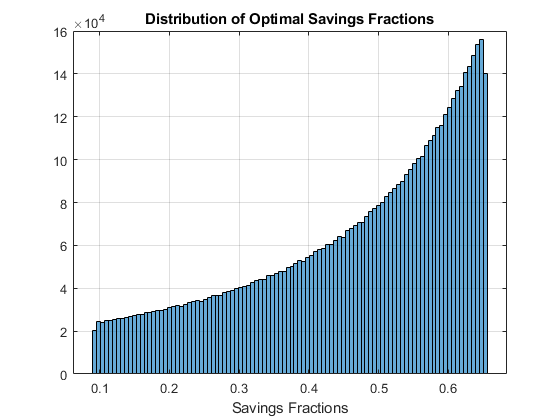

figure();
histogram(ar_opti_save_frac(~isnan(ar_opti_save_frac)),100);
title('Distribution of Optimal Savings Fractions');
xlabel('Savings Fractions');
grid on;

## Define Two Period Intertemporal FOC Log Utility No Shock

See [Household’s Utility Maximization Problem and Two-Period Borrowing and Savings Problem given Endowments](https://fanwangecon.github.io/Math4Econ/derivative_application/htmlpdfm/K_save_households.html).

function [ar_deri_zero, ar_saveborr_level] = ffi_intertemporal_max(ar_saveborr_frac, z1, z2, r, beta)
    ar_saveborr_level = ar_saveborr_frac.*(z1+z2./(1+r)) - z2./(1+r);
    ar_deri_zero = 1./(ar_saveborr_level-z1) + (beta.*(r+1))./(z2 + ar_saveborr_level.*(r+1));
end